close all; clc; clearvars;

T = readtable("CaracteristicasDETECCION2.csv");
T_error = readtable("T_buenacalidad_revisadas_ERRORES.csv");

#### Correlation

images_with_error_SEGM = T_error.image(T_error.error_segmentacion == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_SEGM);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_DISCO = T_error.image(T_error.error_disco == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_DISCO);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_COPA = T_error.image(T_error.error_copa == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_COPA);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

images_with_error_DISCO2 = T_error.image(T_error.error_disco2 == 1);
% Encontrar los índices de las filas en T que tienen imágenes en images_with_error
rows_to_remove = ismember(T.imagen, images_with_error_DISCO2);
% Eliminar las filas que deben ser eliminadas
T(rows_to_remove, :) = [];

% fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg', 'image_0034.jpg', 'image_0035.jpg', 'image_0041.jpg', 'image_0044.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0081.jpg', 'image_0083.jpg', 'image_0084.jpg', 'image_0085.jpg', 'image_0088.jpg', 'image_0089.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0146.jpg','image_0148.jpg', 'image_0153.jpg', 'image_0154.jpg', 'image_0155.jpg', 'image_0164.jpg', 'image_0167.jpg', 'image_0169.jpg', 'image_0170.jpg', 'image_0175.jpg', 'image_0185.jpg', 'image_0189.jpg', 'image_0199.jpg', 'image_0201.jpg',  'image_0216.jpg', 'image_0224.jpg', 'image_0226.jpg', 'image_0227.jpg', 'image_0233.jpg', 'image_0234.jpg',  'image_0237.jpg', 'image_0238.jpg','image_0240.jpg', 'image_0277.jpg', 'image_0313.jpg','image_0317.jpg','image_0320.jpg','image_0321.jpg','image_0325.jpg', 'image_0326.jpg','image_0330.jpg','image_0339.jpg','image_0344.jpg','image_0346.jpg','image_0360.jpg','image_0362.jpg','image_0367.jpg','image_0369.jpg','image_0370.jpg','image_0372.jpg','image_0376.jpg','image_0377.jpg','image_0378.jpg','image_0381.jpg','image_0404.jpg'};
% T = T(ismember(T.imagen, fotos_buenas), :);

% fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg','image_0027.jpg','image_0034.jpg', 'image_0035.jpg',  'image_0044.jpg','image_0048.jpg', 'image_0049.jpg', 'image_0052.jpg', 'image_0053.jpg', 'image_0055.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0084.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0146.jpg','image_0148.jpg'};
% T = T(ismember(T.imagen, fotos_buenas), :);

% [n, m] = size(T);
% for i=1:n
%     disco = imread(['DISCO4', T.imagen{i}]);
%     carpeta_DISCO = 'segmentacion_disco4_BUENAS';
%     mkdir(carpeta_DISCO);
%     
%     nombre_imagen = T.imagen{i};
%     nombre_imagen_con_disco = ['DISCO4_BUENA', nombre_imagen];
%     % Guardar la imagen en la carpeta
%     [~, nombre_sin_extension, extension] = fileparts(nombre_imagen_con_disco);
%     nombre_imagen_guardada = fullfile(carpeta_DISCO, [nombre_sin_extension, extension]);
%     imwrite(disco, nombre_imagen_guardada);
% end
% 
% fotos_malas = {'image_0042.jpg', 'image_0112.jpg', 'image_0135.jpg', 'image_0137.jpg', 'image_0157.jpg', 'image_0184.jpg', 'image_0249.jpg', 'image_0269.jpg', 'image_0283.jpg', 'image_0285.jpg', 'image_0340.jpg', 'image_0354.jpg', 'image_0383.jpg', 'image_0387.jpg', 'image_0402.jpg', 'image_0494.jpg',  'image_0513.jpg', 'image_0540.jpg','image_0562.jpg','image_0580.jpg', 'image_0597.jpg', 'image_0620.jpg', 'image_0647.jpg', 'image_0705.jpg', 'image_0709.jpg',  'image_0730.jpg', 'image_0755.jpg',  'image_0778.jpg', 'image_0783.jpg', 'image_0791.jpg', 'image_0827.jpg', 'image_0841.jpg', 'image_0852.jpg', 'image_0863.jpg','image_0901.jpg', 'image_0902.jpg', 'image_0905.jpg', 'image_0918.jpg', 'image_0921.jpg', 'image_0926.jpg', 'image_0983.jpg','image_1028.jpg',  'image_1031.jpg', 'image_1061.jpg', 'image_10741.jpg', 'image_1082.jpg', 'image_1098.jpg', 'image_1103.jpg', 'image_1126.jpg', 'image_1129.jpg', 'image_1128.jpg', 'image_1163.jpg', 'image_1196.jpg', 'image_1223.jpg',  'image_1228.jpg','image_1229.jpg', 'image_1234.jpg', 'image_1234.jpg', 'image_1244.jpg', 'image_1257.jpg', 'image_1259.jpg', 'image_1268.jpg', 'image_1269.jpg', 'image_1270.jpg','image_1274.jpg','image_1318.jpg',  'image_1345.jpg', 'image_1351.jpg',  'image_1360.jpg', 'image_1356.jpg', 'image_1406.jpg', 'image_1446.jpg', 'image_1454.jpg', 'image_1455.jpg', 'image_1463.jpg','image_1466.jpg', 'image_1469.jpg', 'image_1470.jpg','image_1498.jpg',  'image_1507.jpg', 'image_1567.jpg' };
% rows_to_remove = ismember(T.imagen, fotos_malas);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];

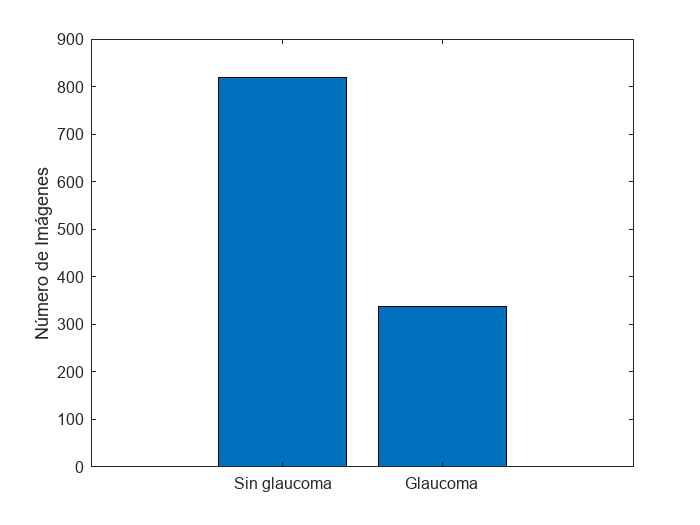

num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});

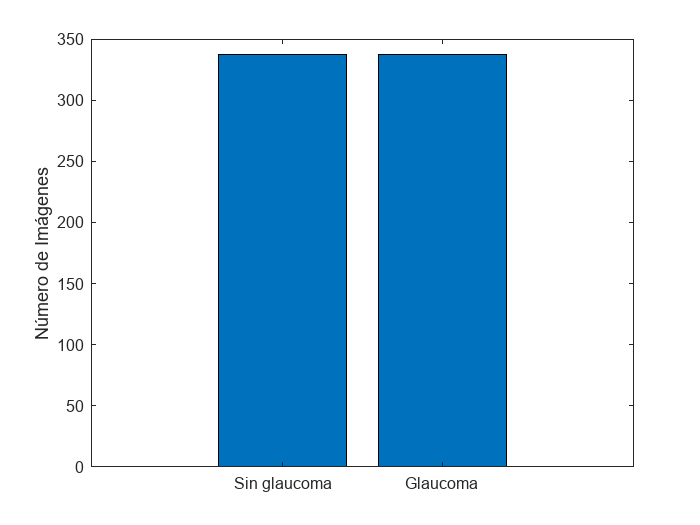


indices_buenas = find(T.glaucoma == 0);
indices_malas = find(T.glaucoma == 1);
rng('default'); % Para reproducibilidad
indices_buenas_seleccionadas = datasample(indices_buenas, num_malas, 'Replace', false);
indices_seleccionados = [indices_buenas_seleccionadas; indices_malas];

% Crear un nuevo conjunto de datos con el mismo número de imágenes en cada clase
T = T(indices_seleccionados, :);
num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});


T.imagen=[];
T.NRR_area_ratio=[];
% T.std_intensidad=[];
T.dist1=[];
T.dist2=[];
T.dist3=[];
T.dist4=[];
T.centro1=[];
T.centro2=[];
% T.nitidez_borde=[];
T.nitidez_bordeG=[];
T.nitidez_bordeR=[];
T.nitidez_bordeB=[];
T.media = [];
T.media_r = [];
T.media_b = [];
T.media_g = [];
T.radioC = [];
T.radioD = [];
% T.var_intensidadR=[];
% T.var_intensidadG=[];
% T.var_intensidadB=[];
% T.entropiaR=[];
% T.entropiaG=[];
% T.entropiaB=[];
% T.rango_dinamicoR=[];
% T.rango_dinamicoG=[];
% T.rango_dinamicoB=[];
% T.entropia=[];
% T.var_intensidad=[];
T.rango_dinamico=[];
T.DDLS=[];
% T.CDR = [];

variables=T.Properties.VariableNames

variables = 1×15 cell array
    {'entropia'}    {'entropiaR'}    {'entropiaG'}    {'entropiaB'}    {'rango_dinamicoR'}    {'rango_dinamicoG'}    {'rango_dinamicoB'}    {'std_intensidad'}    {'var_intensidad'}    {'var_intensidadR'}    {'var_intensidadG'}    {'var_intensidadB'}    {'CDR'}    {'nitidez_borde'}    {'glaucoma'}


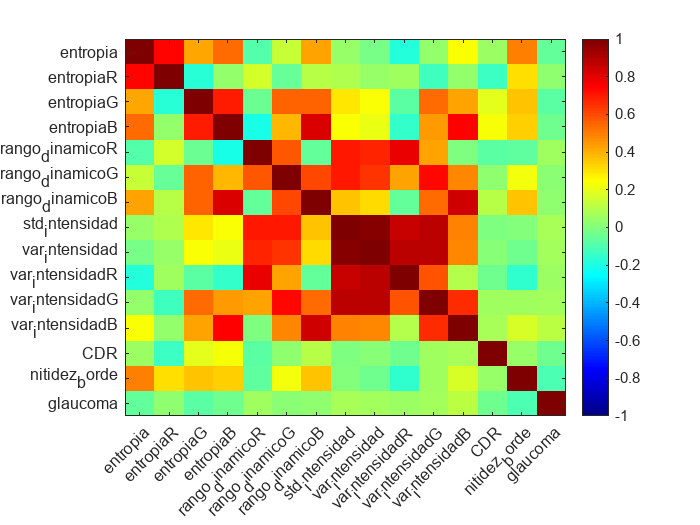


X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));
colormap(jet); colorbar;

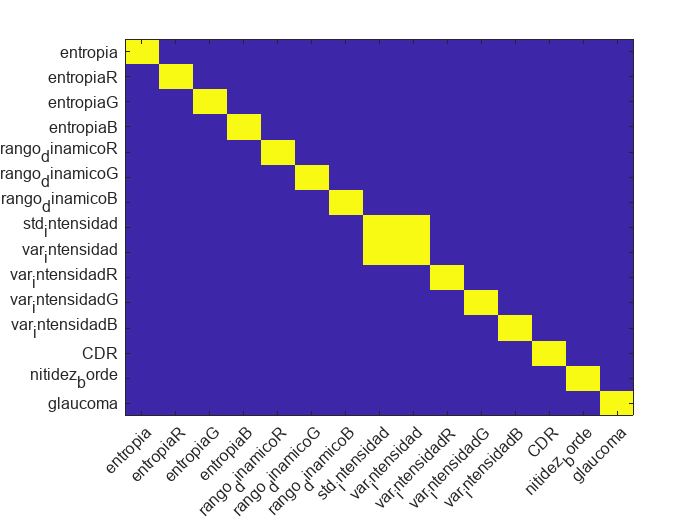


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:30);
xticklabels(variables(:));
yticks(1:30);
yticklabels(variables(:));

#### Preprocessing

[n, ~]=size(T);

T.glaucoma = cellstr(num2str(T.glaucoma)); %convertir quality en variable categorica
for i = 1:n
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No Glaucoma';
    end
end

### 2. Data split

rng(6); 
p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

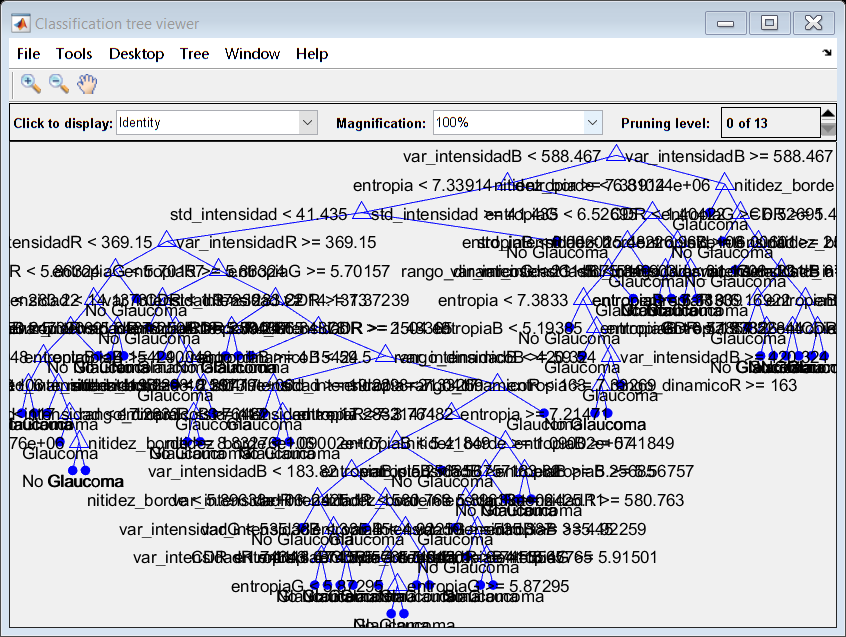

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(T_train.glaucoma, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

first_fold_tree = mdl_tree.Trained{1};
view(first_fold_tree, 'Mode', 'graph');

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
% mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

% mdl_qda = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic','CVPartition',cv_in);
% mdl_loss = kfoldLoss(mdl_qda);
% 
% Y_pred = kfoldPredict(mdl_qda);
% 
% accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
% results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

results

results = 5×3 table
        model         loss      accuracy
    _____________    _______    ________

    "knn"            0.52037    0.47963 
    "tree"            0.4463     0.5537 
    "naive_bayes"     0.4463    0.59074 
    "LDA"            0.42593    0.57407 
    "SVM"            0.52037    0.47963 


[~, best_model] = max(results.accuracy);
results(best_model, :) %balance accuracy

ans = 1×3 table
        model         loss     accuracy
    _____________    ______    ________

    "naive_bayes"    0.4463    0.59074 


### 5. Final model testing

mdl_final_SVM = fitcecoc(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

loss_final2 = 0.5373

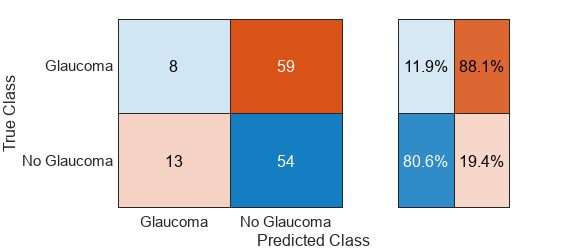

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_LDA = fitcdiscr(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_LDA, T_test);

loss_final2 = loss(mdl_final_LDA, T_test)

loss_final2 = 0.3806

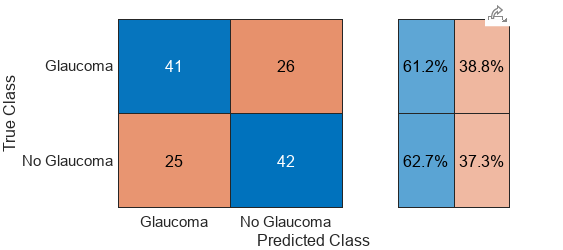

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_tree, T_test);

loss_final2 = loss(mdl_final_tree, T_test)

loss_final2 = 0.4627

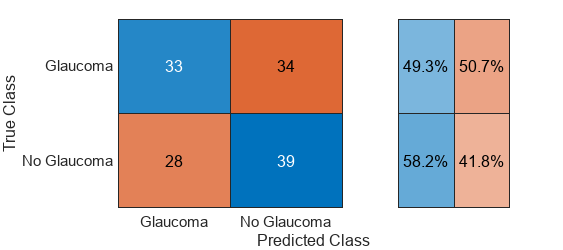

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3);
Y_pred2 = predict(mdl_final_knn, T_test);

loss_final2 = loss(mdl_final_knn, T_test)

loss_final2 = 0.5149

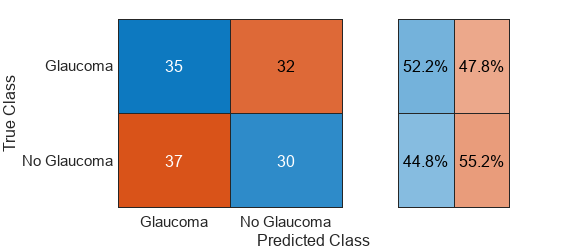

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')


mdl_final_nb = fitcnb(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_nb, T_test);

loss_final2 = loss(mdl_final_knn, T_test)

loss_final2 = 0.5149

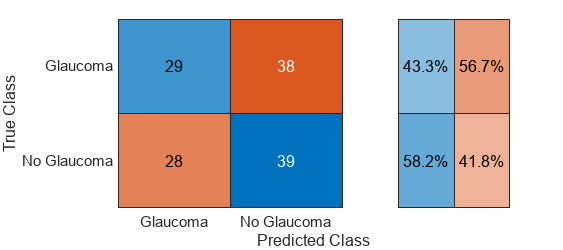

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);

Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized')

% T = readtable("CaracteristicasDETECCION.csv");
% 
% % Realiza las predicciones
% prediccion4 = predict(mdl_final_LDA, T);
% 
% % Convierte las predicciones a 0 y 1
% prediccion_numerica = strcmp(prediccion4, 'Glaucoma');
% 
% % Compara las predicciones numéricas con los valores reales de glaucoma en T
% es_correcto = (prediccion_numerica == T.glaucoma);
% 
% % Crea una nueva tabla que incluya las columnas imagen, glaucoma, prediccion y si la predicción fue correcta o no
% GLAUCOMA_PRED = table(T.imagen, T.glaucoma, prediccion4, es_correcto, 'VariableNames', {'imagen', 'glaucoma', 'prediccion', 'es_correcto'})
% num_correctas = sum(es_correcto)